% Clear workspace
clear; close all; clc;
 
% Images Datapath – Please modify your path accordingly 
datapath='CT2';
 
% Image Datastore
imds=imageDatastore(datapath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
% Determine the split up
total_split=countEachLabel(imds)

total_split = 2×2 table
      Label      Count
    _________    _____

    COVID        5427 
    Non-COVID    2627 


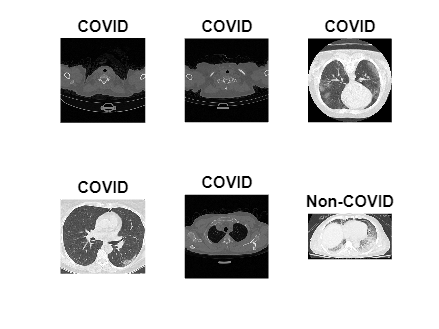



% Number of Images
num_images=length(imds.Labels);

% Visualize random images
perm=randperm(num_images,6);
figure;
for idx=1:length(perm)
    
    subplot(2,3,idx);
    imshow(imread(imds.Files{perm(idx)}));
    title(sprintf('%s',imds.Labels(perm(idx))))
    
end



% Number of folds
num_folds=2;

% Loop for each fold
%for fold_idx=1:num_folds
    
 %   fprintf('Processing %d among %d folds \n',fold_idx,num_folds);
    
   % Test Indices for current fold
   % test_idx=fold_idx:num_folds:num_images;

% Split the Training and Testing Dataset
train_percent=0.80;
[imdsTrain,imdsTest]=splitEachLabel(imds,train_percent,'randomize');
% Split the Training and Validation
valid_percent=0.1;
[imdsValid,imdsTrain]=splitEachLabel(imdsTrain,valid_percent,'randomize');

train_split=countEachLabel(imdsTrain);

    % ResNet Architecture 
    net=resnet50;
    lgraph = layerGraph(net);
    clear net;
    
    % Number of categories
    numClasses = numel(categories(imdsTrain.Labels));
    
    % New Learnable Layer
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
    % Replacing the last layers with new layers
    lgraph = replaceLayer(lgraph,'fc1000',newLearnableLayer);
    newsoftmaxLayer = softmaxLayer('Name','new_softmax');
    lgraph = replaceLayer(lgraph,'fc1000_softmax',newsoftmaxLayer);
    newClassLayer = classificationLayer('Name','new_classoutput');
    lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);
    
      imdsTrain.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsTest.ReadFcn = @(filename)preprocess_Xray(filename);
    imdsValid.ReadFcn = @(filename)preprocess_Xray(filename);
    
 
    
    % Data Augumentation
    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);
    
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
    imdsValidationAug = augmentedImageDatastore([224 224],imdsValid,'DataAugmentation',augmenter);
   

   
imdsTrain.ReadFcn=@(filename)preprocess_images(filename,[lgraph(1).InputSize(1), lgraph(1).InputSize(2)]);
imdsValid.ReadFcn=@(filename)preprocess_images(filename,[lgraph(1).InputSize(1), lgraph(1).InputSize(2)]);


    % Training Options, we choose a small mini-batch size due to limited images 
    options = trainingOptions('adam',...
        'MaxEpochs',10,'MiniBatchSize',8,...
        'Shuffle','every-epoch', ...
        'InitialLearnRate',1e-4, ...
        'Verbose',false, ...
        'Plots','training-progress');
    
    % Data Augumentation
    augmenter = imageDataAugmenter( ...
        'RandRotation',[-5 5],'RandXReflection',1,...
        'RandYReflection',1,'RandXShear',[-0.05 0.05],'RandYShear',[-0.05 0.05]);
    
    % Resizing all training images to [224 224] for ResNet architecture
    auimds = augmentedImageDatastore([224 224],imdsTrain,'DataAugmentation',augmenter);
    
    % Training
    netTransfer = trainNetwork(auimds,lgraph,options);

Error using trainNetwork
Error during read from datastore.

Caused by:
    Error using matlab.io.datastore.ImageDatastore/read
    Error using ReadFcn @(filename)preprocess_images(filename,[lgraph(1).InputSize(1),lgraph(1).InputSize(2)]) for file:
    
        C:\Users\kucaa\Documents\MATLAB\PhD\CT2\COVID\0114.jpg
    
    Unrecognized method, property, or field 'InputSize' for class 'nnet.cnn.LayerGraph'.
    
    Error in untitledResNet50modified

    
    % Resizing all testing images to [224 224] for ResNet architecture   
    augtestimds = augmentedImageDatastore([224 224],imdsTest);
   
    % Testing and their corresponding Labels and Posterior for each Case
    [predicted_labels] = classify(netTransfer,augtestimds);
    
    % Save the Independent ResNet Architectures obtained for each Fold
    %save(sprintf('ResNet50_%d_among_%d_folds',fold_idx,num_folds),'netTransfer','test_idx','train_idx');
    
    % Clearing unnecessary variables 
    % clearvars -except fold_idx num_folds num_images predicted_labels posterior imds netTransfer;
    
%end

% Actual Labels
actual_labels=imds.Labels;

% Confusion Matrix
figure;
plotconfusion(actual_labels,predicted_labels')
title('Confusion Matrix');


test_labels=double(nominal(imds.Labels));

% ROC Curve - Our target class is the first class in this scenario 
[fp_rate,tp_rate,T,AUC]=perfcurve(test_labels,posterior(:,1),1);
figure;
plot(fp_rate,tp_rate,'b-');
grid on;
xlabel('False Positive Rate');
ylabel('Detection Rate');

% Area under the ROC curve value
AUC

cm = confusionmat(actual_labels, predicted_labels);
cmt = cm'

diagonal = diag(cmt)
sum_of_rows = sum(cmt, 2)

precision = diagonal ./ sum_of_rows
overall_precision = mean(precision)

sum_of_columns = sum(cmt, 1)

recall = diagonal ./ sum_of_columns'
overall_recall = mean(recall)

f1_score = 2*((overall_precision*overall_recall)/(overall_precision+overall_recall))


function Iout=preprocess_images(filename,desired_size)



% Read the Image
I=imread(filename);

% Some images might be grayscale, replicate the image 3 times to
% create an RGB image.

if ismatrix(I)
  I=cat(3,I,I,I);
end

% Conversion to Double for calculation purposes
I=double(I);

% Mean Calculation
Ir=I(:,:,1);mu_red=mean(Ir(:));
Ig=I(:,:,2);mu_green=mean(Ig(:));
Ib=I(:,:,3);mu_blue=mean(Ib(:));
mean_value=(mu_red+mu_green+mu_blue)/3;

% Scaling the Image for Color constancy
Iout(:,:,1)=I(:,:,1)*mean_value/mu_red;
Iout(:,:,2)=I(:,:,2)*mean_value/mu_green;
Iout(:,:,3)=I(:,:,3)*mean_value/mu_blue;

% Converting it back to uint8
Iout=uint8(Iout);

% Resize the image
Iout=imresize(Iout,[desired_size(1) desired_size(2)]);
end


function Iout = preprocess_Xray(filename)
% Read the Filename
I = imread(filename);
% Some images might be RGB, convert them to Grayscale
if ~ismatrix(I)
    I=rgb2gray(I); 
end
% Replicate the image 3 times to create an RGB image
Iout = cat(3,I,I,I);
end


